# Quiescent Data Processing

## Load, Detrend, and Determine Std of Each Sensing Axis

First, load the data from the file VN200_accel_gyro_8_hr.mat

close all
clear all
clc

load('VN200_accel_gyro_8_hr.mat')
 % This will be commented out such that > 50MB is loaded every run of the
 % program, its only loaded the first time

## Let's plot the quiescent data, and determine the std dev for each axis of both sensors

 % Time Vector
 t = (0 : (1/Fs) : (length(accel)/Fs - 1/Fs))';
 t_hrs = t ./ 3600;
 axis_str = ['X', 'Y', 'Z'];
 clr_str = ['r', 'g', 'b'];

 % Convert and Detrend Data
 accel = detrend(accel); 
 gyro = detrend(gyro);
 
 % Convert to milli-g's
 accel_mg = accel * 100; % assumes g = 10 m/s^2

 % Convert to Degrees per Hour
 gyro_dh = 180/pi * 3600 * gyro;
 
%  % Plot Data for each sensing axis
%  for ii = 1 : 3
%      
%      % Accel Std Dev
%      accel_std(ii,1) = sqrt(var(accel(:,ii)));
%      
%      % Plot Accel Quiescent Data
%      figure(1)
%      subplot(3, 1, ii)
%      hold on
%      plot(t_hrs, accel(:,ii), clr_str(ii))
%      line([t_hrs(1) t_hrs(end)], [-accel_std(ii) -accel_std(ii)], 'Color', 'k', 'LineStyle', '--')
%      line([t_hrs(1) t_hrs(end)], [0 0], 'Color', 'k', 'LineStyle', ':')
%      line([t_hrs(1) t_hrs(end)], [accel_std(ii) accel_std(ii)], 'Color', 'k', 'LineStyle', '--')
%      title([axis_str(ii), ' Accel Std Dev:  ', num2str(accel_std(ii,1))])
%      xlabel('Time (hours)')
%      ylabel([axis_str(ii), 'Accel (m/s^2)'])
%      grid on
%      hold off
%      
%      % Gyro Std Dev
%      gyro_std(ii,1) = sqrt(var(gyro(:,ii)));
%      
%      % Plot Gyro Quiescent Data
%      figure(2)
%      subplot(3, 1, ii)
%      hold on
%      plot(t_hrs, gyro(:,ii), clr_str(ii))
%      line([t_hrs(1) t_hrs(end)], [-gyro_std(ii) -gyro_std(ii)], 'Color', 'k', 'LineStyle', '--')
%      line([t_hrs(1) t_hrs(end)], [0 0], 'Color', 'k', 'LineStyle', ':')
%      line([t_hrs(1) t_hrs(end)], [gyro_std(ii) gyro_std(ii)], 'Color', 'k', 'LineStyle', '--')
%      title([axis_str(ii), ' Gyro Std Dev:  ', num2str(gyro_std(ii,1))])
%      xlabel('Time (hours)')
%      ylabel([axis_str(ii), 'Gyro (rad/s)'])
%      grid on
%      hold off
%      
%  end
%  % Print Results
%  format shorte
% row_names = {'X axis', 'Y axis', 'Z axis'};
% column_names = {'Accel White Noise Std Dev (m/s^2)'};
% T = array2table(accel_std, "RowNames", row_names, "VariableNames", column_names)
% row_names = {'X axis', 'Y axis', 'Z axis'};
% column_names = {'Gyro White Noise Std Dev (rad/s)'};
% T = array2table(gyro_std, "RowNames", row_names, "VariableNames", column_names)
%  save("IMU_Cal_Varying_Error_Sources.mat", "accel_std", "gyro_std");

## PSD of Each Sensing Axis

Using 'pwelch' to accomplish the analysis

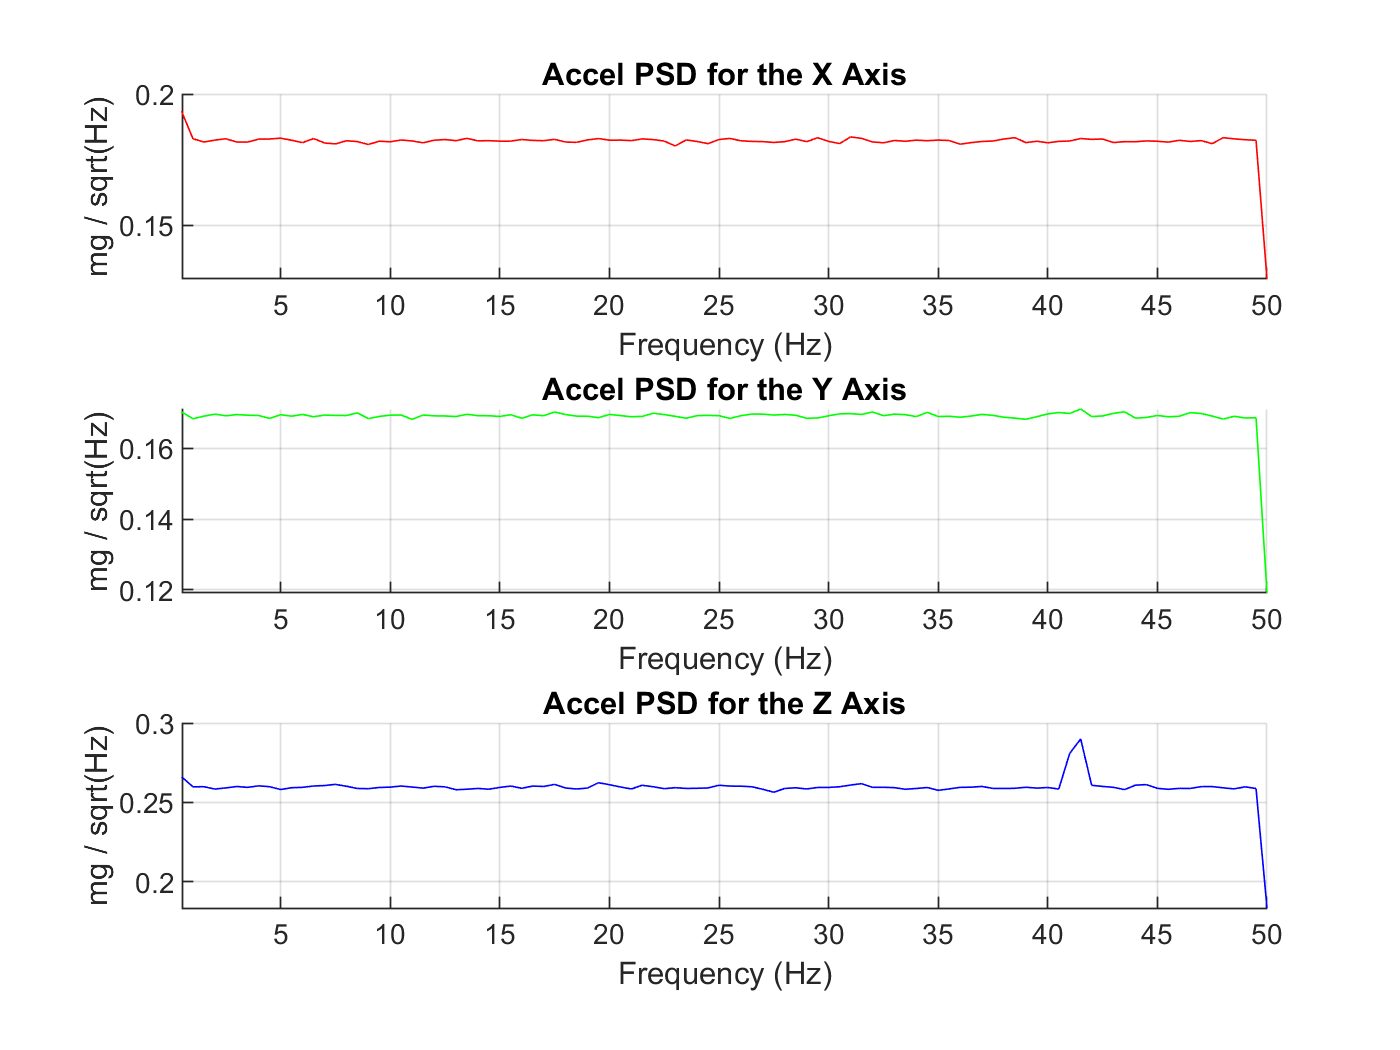

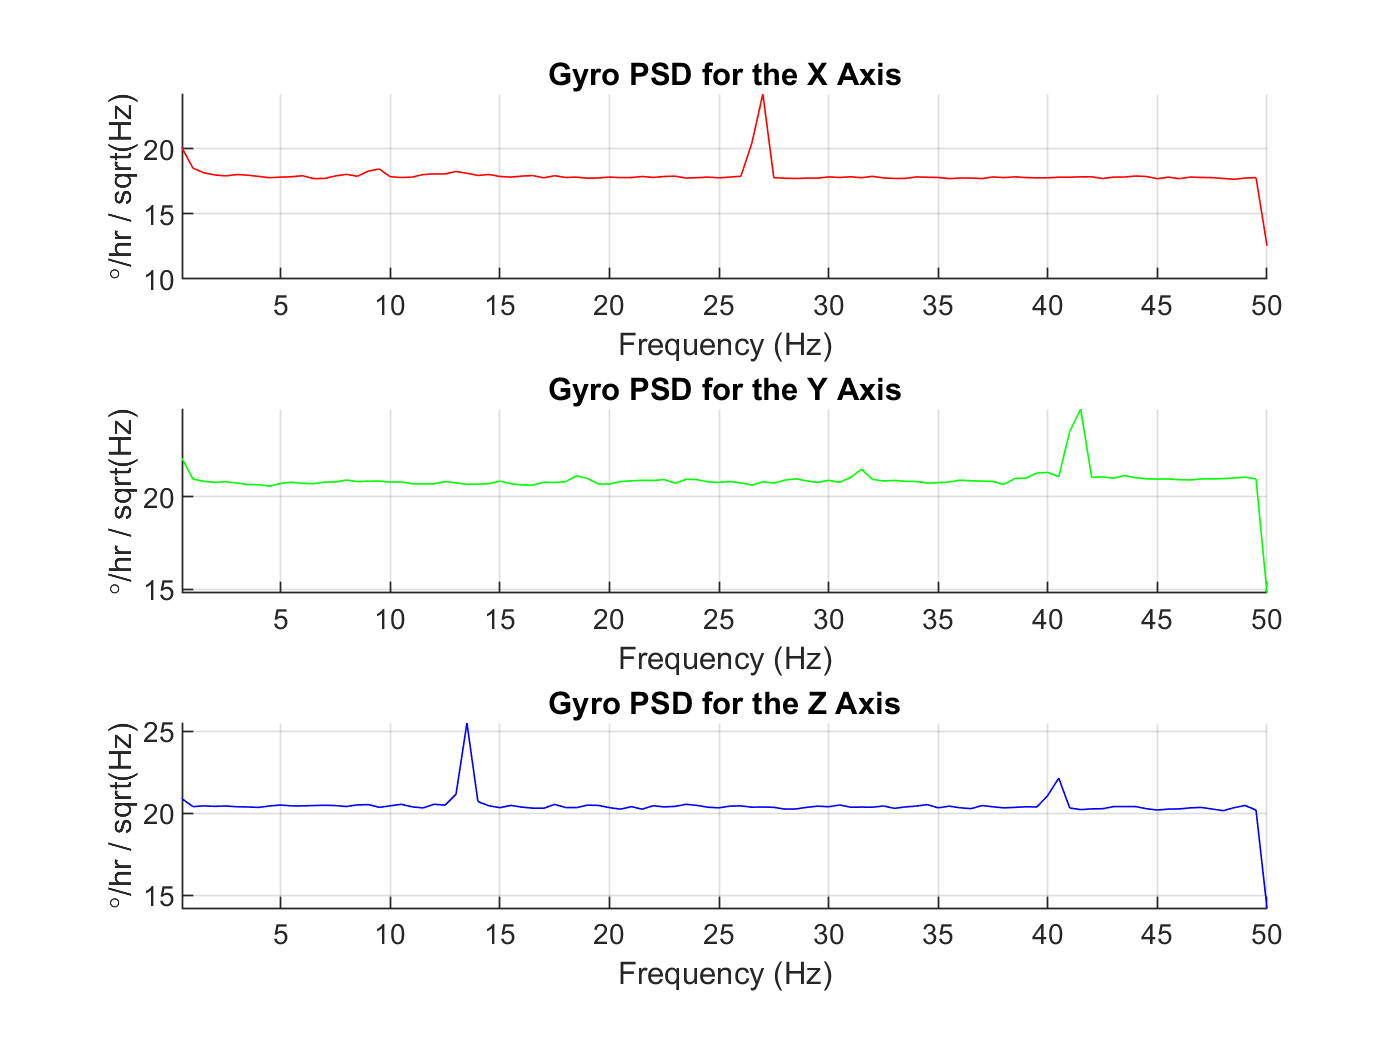

 nfft = floor(2*Fs);
 
 for ii = 1 : 3
     
     % Accel PSD
     figure(3)
     subplot(3, 1, ii)
     hold on
     [pxx_a(ii,:), f_a(ii,:)] = pwelch(accel_mg(:,ii), 256, [], nfft, Fs);
%      pwelch(accel(:,ii) - mean(accel(:,ii)), [], [], nfft, Fs, "onesided", "psd")
     sqrt_pxx_a(ii,:) = sqrt(pxx_a(ii,:));
     plot(f_a(ii,:), sqrt_pxx_a(ii,:), clr_str(ii))
     title(['Accel PSD for the ', axis_str(ii), ' Axis'])
     xlabel('Frequency (Hz)')
     ylabel('mg / sqrt(Hz)')
     xlim([0.5, 50])
     grid on
     hold off
     
     % Gyro PSD
     figure(4)
     subplot(3, 1, ii)
     hold on
     [pxx_g(ii,:), f_g(ii,:)] = pwelch(gyro_dh(:,ii), 256, [], nfft, Fs);
     sqrt_pxx_g(ii,:) = sqrt(pxx_g(ii,:));
     plot(f_g(ii,:), sqrt_pxx_g(ii,:), clr_str(ii))
     title(['Gyro PSD for the ', axis_str(ii), ' Axis'])
     xlabel('Frequency (Hz)')
     ylabel('\circ/hr / sqrt(Hz)')
     xlim([0.5, 50])
     grid on
     hold off
     
 end

 % Capturing Parameters on each axis
 for ii = 1 : 3
     
     % PSD Directly from the One Sided PSD
     accel_PSD(ii,1) = mean(sqrt_pxx_a(ii,10:end));
     gyro_PSD(ii,1) = mean(sqrt_pxx_g(ii,10:end));
     
     % VRW in [m/s/sqrt(hr)] -- ARW in [deg/sqrt(hr)]
     accel_VRW(ii,1) = 60/100 * accel_PSD(ii,1);
     gyro_ARW(ii,1) = (1/60) * gyro_PSD(ii,1);
     
     % sigma_VRW in [m/s^2] -- sigma_ARW in [rad/s]
     sigma_VRW(ii,1) = accel_PSD(ii,1) * sqrt(Fs)/100;
     sigma_ARW(ii,1) = gyro_PSD(ii,1) * (pi*sqrt(Fs))/(180*3600);
     
 end
 
 % Display Results
 format shorte
 accel_table = [accel_PSD, accel_VRW, sigma_VRW];
 row_names = {'X', 'Y', 'Z'};
 column_names = {'Accel PSD   [mg / sqrt(Hz)]', 'Accel VRW   [m/s / sqrt(hr)]', 'sigma_VRW   [m / s^2]'};
 T = array2table(accel_table, "RowNames", row_names, "VariableNames", column_names)

T = 3×3 table
         Accel PSD   [mg / sqrt(Hz)]    Accel VRW   [m/s / sqrt(hr)]    sigma_VRW   [m / s^2]
         ___________________________    ____________________________    _____________________

    X            1.8161e-01                      1.0896e-01                  1.8161e-02      
    Y            1.6877e-01                      1.0126e-01                  1.6877e-02      
    Z            2.5922e-01                      1.5553e-01                  2.5922e-02      


gyro_table = [gyro_PSD, gyro_ARW, sigma_ARW];
row_names = {'X', 'Y', 'Z'};
column_names = {'Gyro PSD   [deg/hr / sqrt(Hz)]', 'Gyro ARW   [deg / sqrt(hr)]', 'sigma_ARW   [rad / s]'};
T = array2table(gyro_table, "RowNames", row_names, "VariableNames", column_names)

T = 3×3 table
         Gyro PSD   [deg/hr / sqrt(Hz)]    Gyro ARW   [deg / sqrt(hr)]    sigma_ARW   [rad / s]
         ______________________________    ___________________________    _____________________

    X              1.7864e+01                      2.9774e-01                  8.6609e-04      
    Y              2.0883e+01                      3.4805e-01                  1.0124e-03      
    Z              2.0414e+01                      3.4023e-01                  9.8970e-04      


 save("IMU_Cal_Varying_Error_Sources.mat", "accel_VRW", "gyro_ARW", "sigma_VRW", "sigma_ARW", '-append');
 clear pxx_a f_a pxx_g f_g

## Copy of Dr. Bruder's AllanVar Code

I couldn't get mine working, so here's this one.  

*** Important!  Currently missing the Correlation Time $T_x$ to perform the proper conversion, assuming a value of 0.1 for now ***

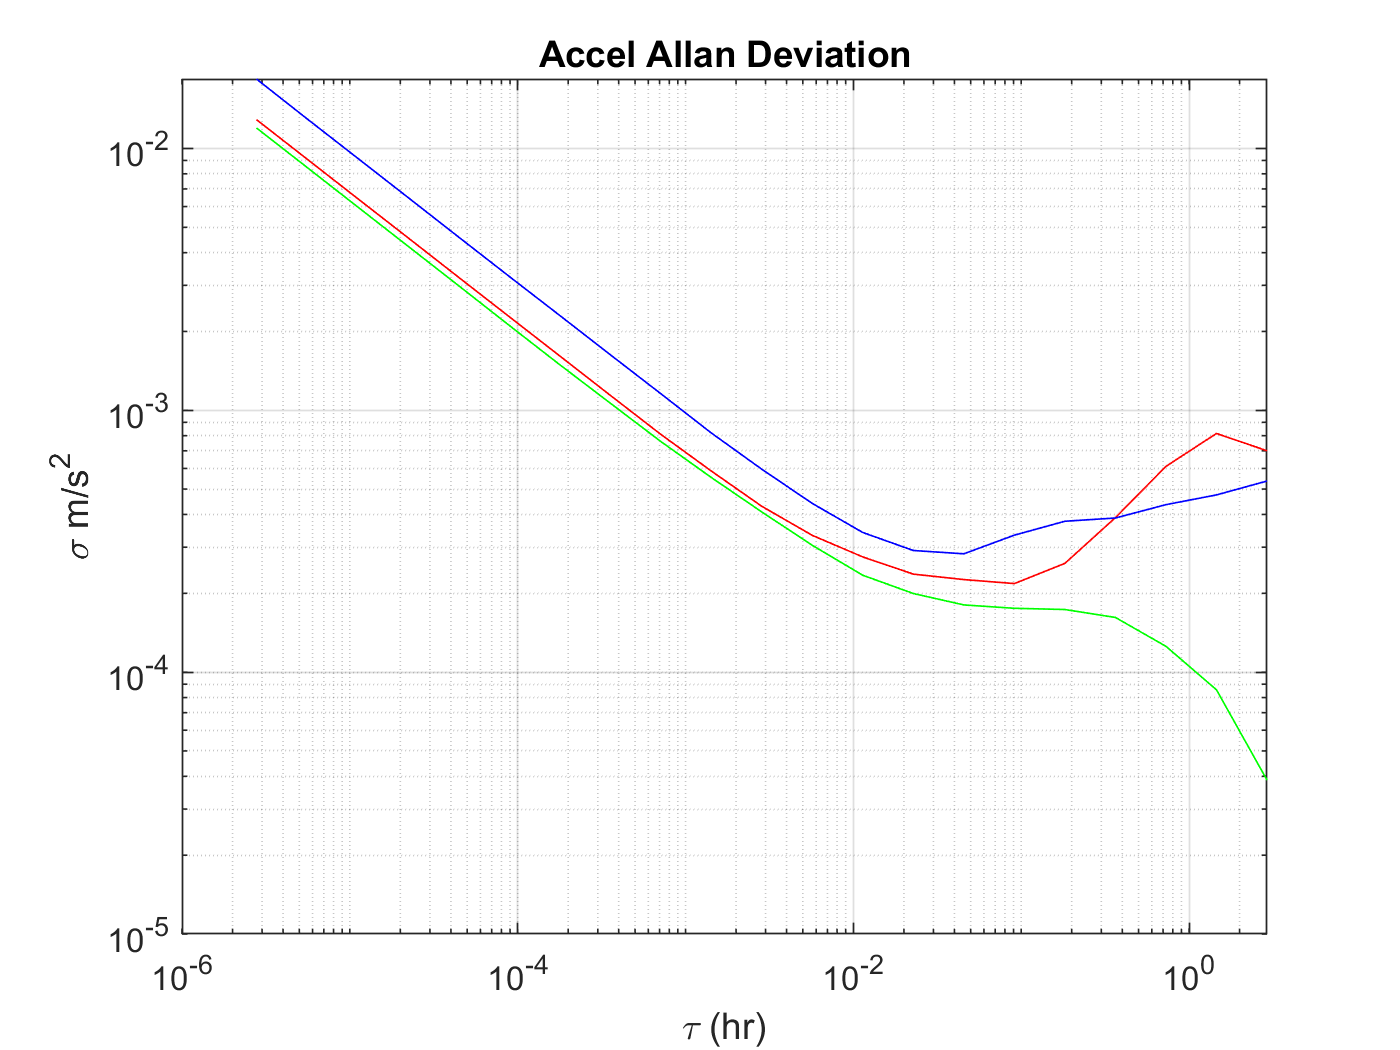

% Accel Allan Var
[avar_x,tau] = allanvar(accel(:,1),'octave',Fs);
[avar_y,tau] = allanvar(accel(:,2),'octave',Fs);
[avar_z,tau] = allanvar(accel(:,3),'octave',Fs);

figure
loglog(tau/3600,sqrt(avar_x), 'r', tau/3600,sqrt(avar_y), 'g', tau/3600,sqrt(avar_z), 'b')
title('Accel Allan Deviation')
xlabel('\tau (hr)')
ylabel('\sigma m/s^2')
grid on


% Converting BI_VRW to sigma_n_accel
T_a = 0.1; % see important note above
BI_VRW = [min(sqrt(avar_x(1:18))); min(sqrt(avar_y(1:18))); min(sqrt(avar_z(1:18)))];
sigma_BI_VRW = (60 / sqrt(Fs)) * BI_VRW;
sigma_n_accel = (1 - exp(-2*(1/(Fs*T_a)))) * sigma_BI_VRW;

% Display Results
format shorte
row_names = {'X axis', 'Y axis', 'Z axis'};
column_names = {'Accel Bias Instabiliy Sigma (m/s^2)'};
T = array2table(sigma_n_accel, "RowNames", row_names, "VariableNames", column_names)

T = 3×1 table
              Accel Bias Instabiliy Sigma (m/s^2)
              ___________________________________

    X axis                2.3699e-04             
    Y axis                1.7592e-04             
    Z axis                3.0788e-04             


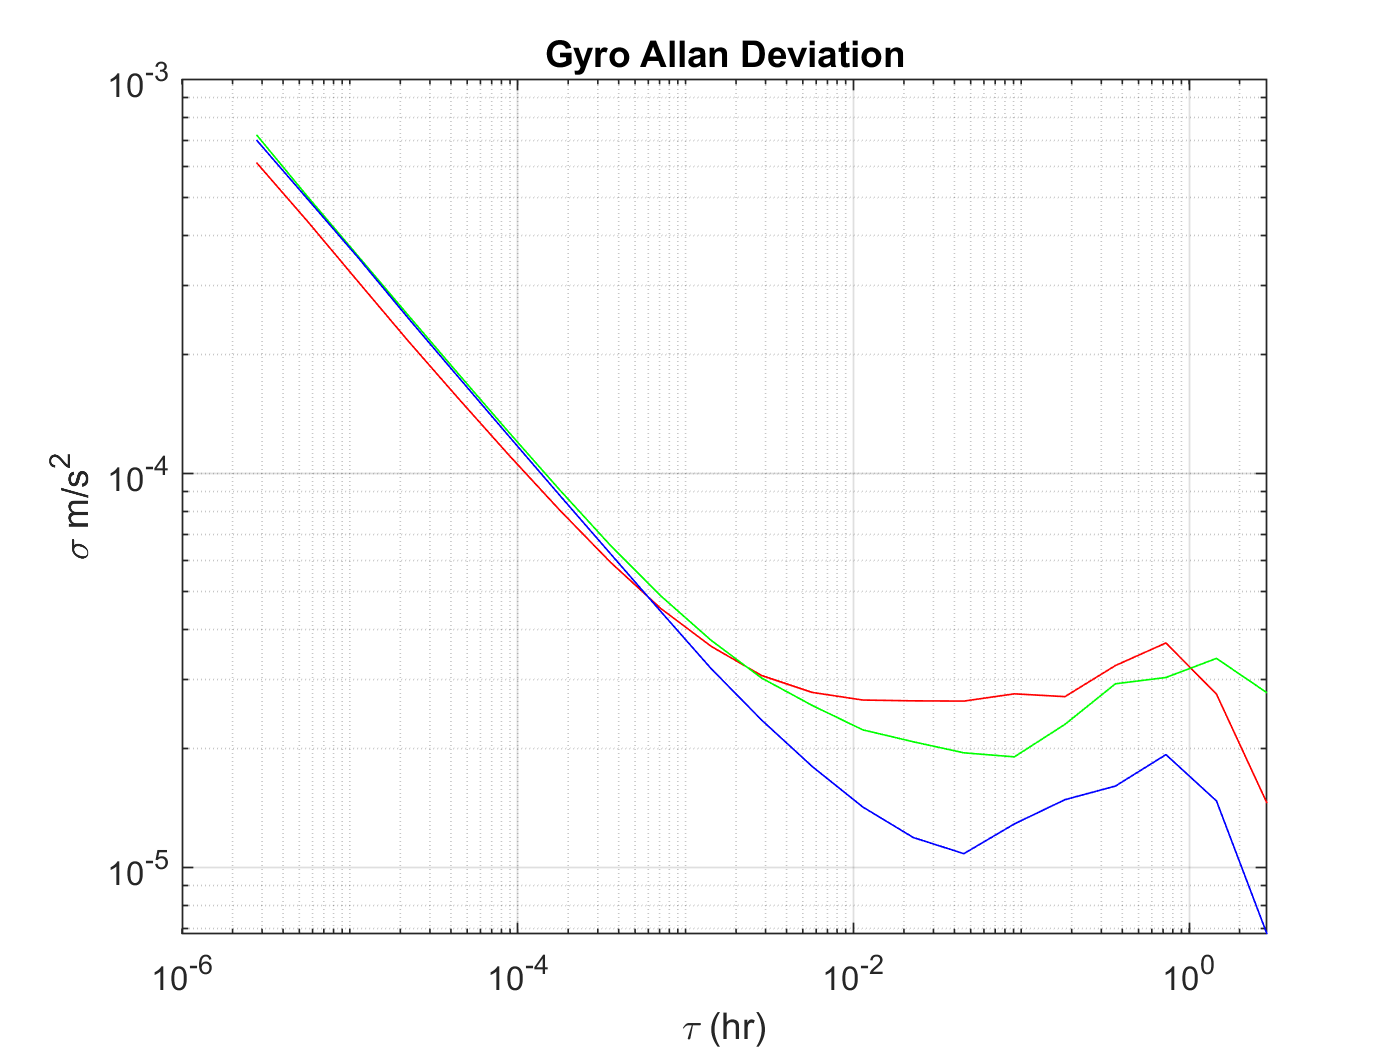


% Gyro Allan Var
[avar_x,tau] = allanvar(gyro(:,1),'octave',Fs);
[avar_y,tau] = allanvar(gyro(:,2),'octave',Fs);
[avar_z,tau] = allanvar(gyro(:,3),'octave',Fs);

figure
loglog(tau/3600,sqrt(avar_x), 'r', tau/3600,sqrt(avar_y), 'g', tau/3600,sqrt(avar_z), 'b')
title('Gyro Allan Deviation')
xlabel('\tau (hr)')
ylabel('\sigma m/s^2')
grid on


% Converting BI_ARW to sigma_n_gryo
T_g = 0.1; % see important note above
BI_ARW = [min(sqrt(avar_x(1:18))); min(sqrt(avar_y(1:18))); min(sqrt(avar_z(1:18)))];
sigma_BI_ARW = (60 / sqrt(Fs)) * BI_ARW;
sigma_n_gyro = (1 - exp(-2*(1/(Fs*T_g)))) * sigma_BI_ARW;

% Display Results
row_names = {'X axis', 'Y axis', 'Z axis'};
column_names = {'Gyro Bias Instabiliy Sigma (deg/hr)'};
T = array2table(sigma_n_gyro * (180/pi * 3600), "RowNames", row_names, "VariableNames", column_names)

T = 3×1 table
              Gyro Bias Instabiliy Sigma (deg/hr)
              ___________________________________

    X axis                5.9229e+00             
    Y axis                4.2763e+00             
    Z axis                2.4292e+00             



% Save Data
save("IMU_Cal_Varying_Error_Sources.mat", "sigma_n_gyro", "sigma_n_accel", '-append')

## AutoCorrelation

Last meeting, we discussed the autocorrellation plots and how the additive white noise contribution dominates the autocorrellation function which prevents from finding the time constant associated with the bias instability.  We discussed the idea of passing the data through a low pass filter to remove a majority of the white noise, and perhaps that might reveal the bias instability time constant.  So that is what I'm going to try here.  Let's see what happens.  

I'm just going to try first-order LPF's with the following cut-off frequencies: 40 Hz, 30 Hz, 20Hz, 10 Hz.  

I'm going to use the MATLAB 'filterDesigner' tool to grab the filter coefficents, save them to a .mat file, and load them into the workspace so this is repeatable.  We haven't covered LPF's in detail in DSP yet, so I'll just go this route for now.  I'm sure its not difficult, but I'd just like to make sure its done correctly for now.  

The filterDesigner setting is a low-pass FIR, minimum-order, Fs = 100, F_pass = f_c , F_stop = f_c + 1 (i.e. F_pass = 40, F_stop = 41), and A_pass = 0.5, A_stop = 20     (so basically a 20 dB cut-off)

%  % Load coeff.mat
%  % This file contains the filter coefficents for the cut-off frequencies
%  load('coeff.mat')
%  
%  % Filter the Data for each hypothesis
%  for ii = 1 : 3
%      
%      % Accel Filtering
%      a40(:,ii) = filter(b_40, [1], accel(:,ii));
%      a30(:,ii) = filter(b_30, [1], accel(:,ii));
%      a20(:,ii) = filter(b_20, [1], accel(:,ii));
%      a10(:,ii) = filter(b_10, [1], accel(:,ii));
%      a5(:,ii) = filter(b_5, [1], accel(:,ii));
%      a2(:,ii) = filter(b_2, [1], accel(:,ii));
%      
%      % Gyro Filtering
%      g40(:,ii) = filter(b_40, [1], gyro(:,ii));
%      g30(:,ii) = filter(b_30, [1], gyro(:,ii));
%      g20(:,ii) = filter(b_20, [1], gyro(:,ii));
%      g10(:,ii) = filter(b_10, [1], gyro(:,ii));
%      g5(:,ii) = filter(b_5, [1], gyro(:,ii));
%      g2(:,ii) = filter(b_2, [1], gyro(:,ii));
%      
%  end
%  
%  % Run the AutoCorrelation Algorithm on all these data sets
%  % ACTUALLY, lets focus on just the x-accel for now.  
%  
%  N = 1000; % ten seconds
%  a_filt = [a40((1:N),1)'; a30((1:N),1)'; a20((1:N),1)'; a10((1:N),1)'; a5((1:N),1)'; a2((1:N),1)'];
% 
% for ii = 1 : length(a_filt(:,1)) % for each filtered set of data
%     for k = 1 : N % each index of R_xx
%         
%         %  Zero Pad each vector of data
%         a_k = [zeros(1,(k-1)), a_filt(ii,:)];
%         a = [a_filt(ii,:), zeros(1,(k-1))];
%         
%         % Autocorreclation of the Accelerometer Axis
%         Rxx_accel(ii, k) = (1/N) * sum(a_k .* a);
%         
%     end
% end
% 
% % Plot Results
% freq_str = [40, 30, 20, 10, 5, 2];
% for jj = 1 : length(a_filt(:,1))
%     
%     figure(jj+6)
%     hold on
%     plot(t(1:N), Rxx_accel(jj,:), 'r')
%     title(['LPF Cutoff Frequency:  ', num2str(freq_str(jj)), ' Hz'])
%     xlabel('Time (s)')
%     ylabel('R_x_x')
%     grid on
%     
%     % Draw Line for 63% Drop
%     line_63 = 0.63 * Rxx_accel(jj,1);
%     line([t(1), t(N)], [line_63 line_63], 'Color', 'k', 'LineStyle', '--')
%     hold off
%     
% end

Looking at the following ways you could filter the data, it seems highly dependant which frequency you select to determine your time constant for the bias instability.  Perhaps there are better filter choices, or a better approach in general? 